%% 基于 CORA 2024 的无人机数值误差安全边界验证
clear; clc; close all;

% 1. 引入闭环 PD 控制器，构建稳定的动力学矩阵 A
% 状态向量: x = [位置; 速度]
% 控制律: 加速度 a = -Kp*位置 - Kd*速度
Kp = 5;      % 比例增益 (代表刚度)
Kd = 2.5;    % 微分增益 (代表阻尼)
A_closed = [0 1; -Kp -Kd];

% 将数值截断误差等效为一个作用于系统状态的“输入矩阵”
% 假设误差同时影响位置和速度的导数方程
B_error = [1; 1];

% 2. 定义数值解法的“截断误差包络”
% 假设我们分析的是前向欧拉法，步长 h=0.02s
% 理论推导表明，其局部截断误差界限大概在 0.05 左右
error_bound = 0.08; 
% 将截断误差定义为系统的有界扰动集合 (Zonotope)
U_error = zonotope(0, error_bound); 

% 3. 创建 CORA 连续系统模型 (包含扰动)
% 严格按照位置传入：(系统名称, A矩阵, B矩阵)
sys = linearSys('DroneErrorSys', A_closed, B_error);

% 4. 设置可达性分析参数 (Reachability Options)
params.tFinal = 4.0;            % 验证 4 秒内的安全性
% 初始状态集合：给无人机一个极大的初始向前速度 (2.5 m/s) 和一点初始位置偏差
params.R0 = zonotope([-0.2; 2.5], diag([0.02, 0.02])); 
% 控制输入+误差集合
params.U = U_error; 

% CORA 算法配置选项
options.tFinal = 4.0;            % 验证 4 秒内的安全性
options.timeStep = 0.02;         % CORA 计算的时间步长
options.alg = 'lin';            % 线性系统算法
options.tensorOrder = 2;        % 泰勒展开阶数
options.taylorTerms = 4;         % 残差计算的张量阶数
options.zonotopeOrder = 50;     % Zonotope的复杂度上限(决定计算速度与精度)

% 5. 执行核心计算：求解可达管 (ReachTube)
fprintf('正在计算考虑闭环受控状态下 ODE 数值误差的无人机可达管...\n');

正在计算考虑闭环受控状态下 ODE 数值误差的无人机可达管...


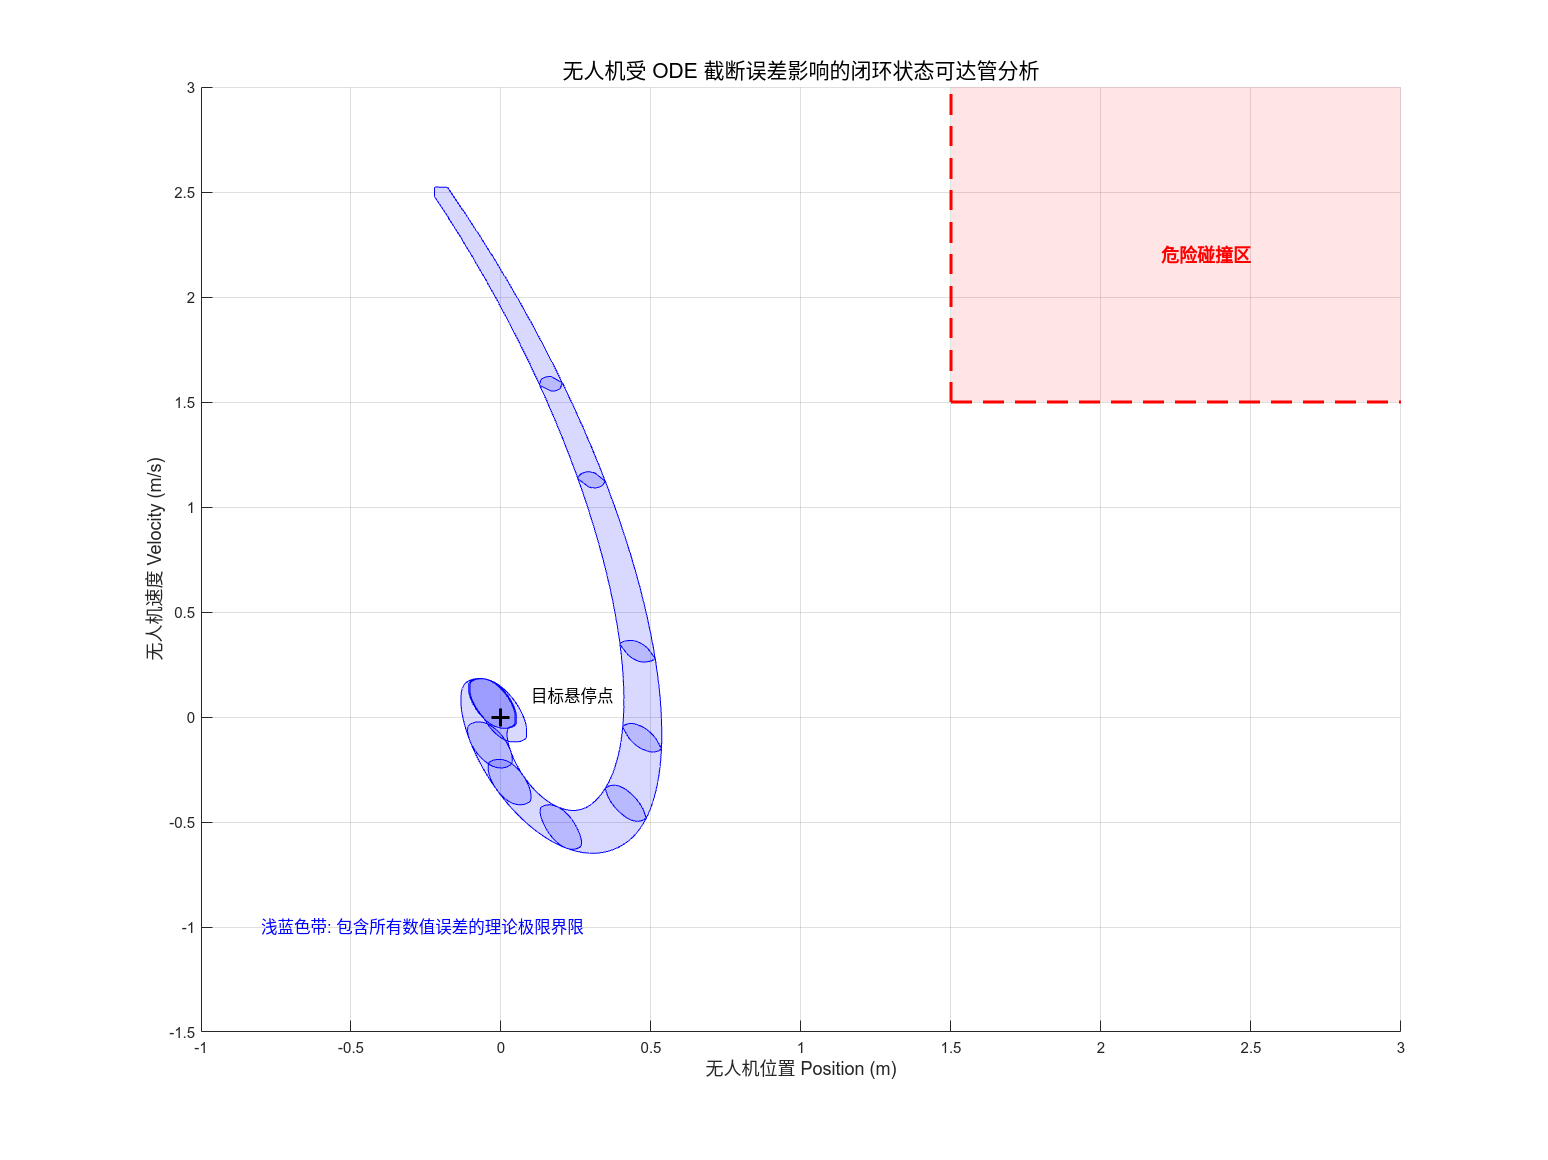

R = reach(sys, params, options);

%% 6. 绘图与安全边界验证
figure('Color', 'w', 'Position', [100, 100, 800, 600]);
hold on; grid on;

% 绘制可达管 (X轴为位置，Y轴为速度)
plot(R, [1, 2], 'b', 'EdgeColor', 'b', 'FaceAlpha', 0.15); 

% 绘制安全边界 (右上角的危险区)
plot([1.5, 3], [1.5, 1.5], 'r--', 'LineWidth', 2); % 速度墙
plot([1.5, 1.5], [1.5, 3], 'r--', 'LineWidth', 2); % 位置墙
fill([1.5, 3, 3, 1.5], [1.5, 1.5, 3, 3], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
text(2.2, 2.2, '危险碰撞区', 'Color', 'r', 'FontSize', 12, 'FontWeight', 'bold');

% 标注原点 (控制器的目标悬停点)
plot(0, 0, 'k+', 'MarkerSize', 12, 'LineWidth', 2);
text(0.1, 0.1, '目标悬停点', 'FontSize', 11);

title('无人机受 ODE 截断误差影响的闭环状态可达管分析', 'FontSize', 14);
xlabel('无人机位置 Position (m)', 'FontSize', 12);
ylabel('无人机速度 Velocity (m/s)', 'FontSize', 12);
xlim([-1, 3]);
ylim([-1.5, 3]);

% 答辩核心观点标注
text(-0.8, -1.0, '浅蓝色带: 包含所有数值误差的理论极限界限', 'Color', 'b', 'FontSize', 11);